# Statistical Analysis

**1. Data Collection**

**2. Organization of Data**

**3. Analysis and Interpretation**

**4. Presentation**

## Importing Data from Microsoft Excel

filename = 'Test.xlsx';
sheet = 1;
xlRange = 'A1:B360';
subsetA = xlsread(filename,sheet,xlRange)

subsetA =     1.0000    0.9998
    2.0000    0.9994
    3.0000    0.9986
    4.0000    0.9976
    5.0000    0.9962
    6.0000    0.9945
    7.0000    0.9925
    8.0000    0.9903
    9.0000    0.9877
   10.0000    0.9848


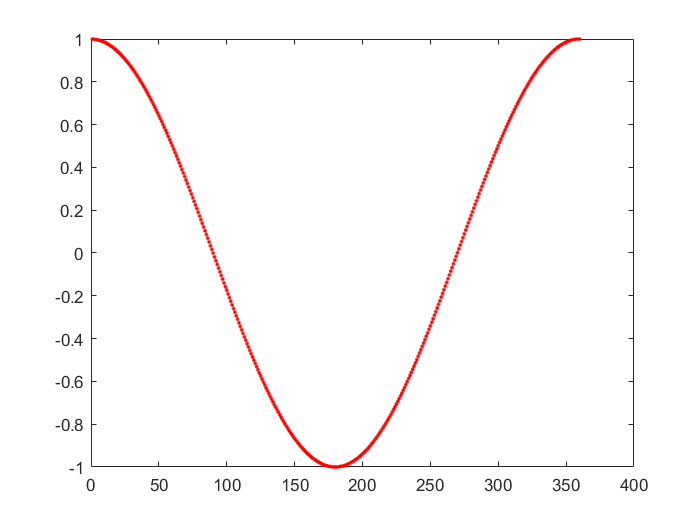

plot(subsetA(:,1),subsetA(:,2),'r.')

# Interpolation Techniques

**Used to fill in the data between a given range.**

**interpl(x,y)**

**1. Linear Interpolation**

-     Requires atleast 2 points

**2. Spline Interpolation**

-     Requires atleast 4 points

**3. Piecewise Cubic Hermite Polynomial**

-     Requires atleast 4 points

-     Shape preserving piecewise cubic interpolation

**Q. Obtain a smooth sine curve using following data points:**

x =  0 45 135 180 225 315 360

y = 0 0.7071 0.7071 0 -0.7071 -0.7071 0

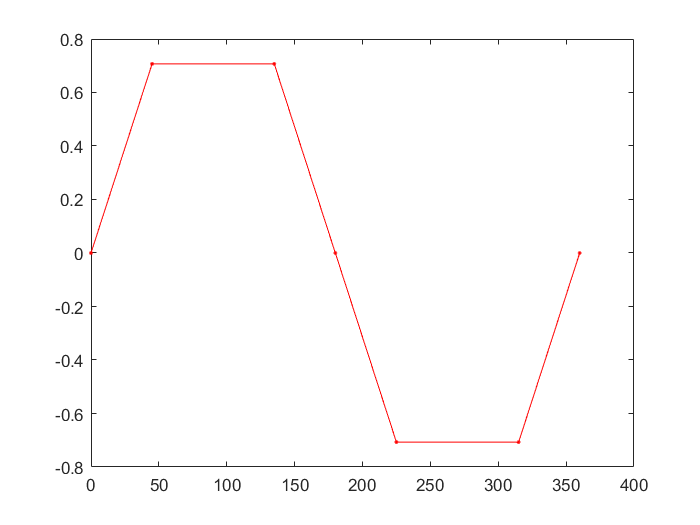

x = [0, 45, 135, 180, 225, 315, 360];
y = [0, 0.7071, 0.7071, 0, -0.7071, -0.7071, 0];
plot(x, y ,'r.-')

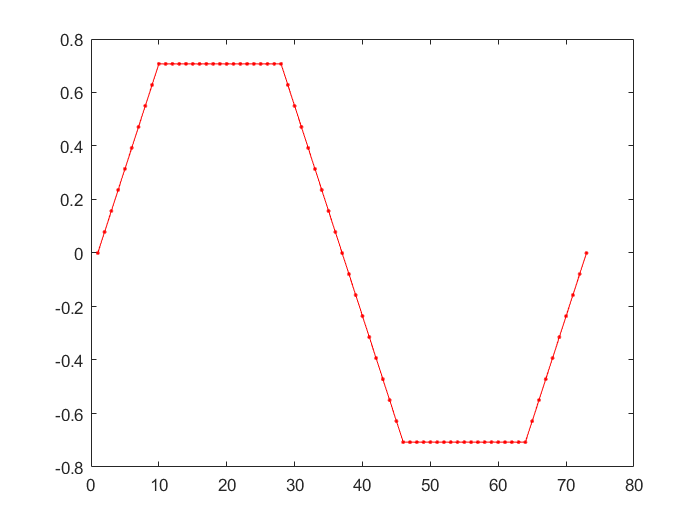

% Interpolating the values
xq = 0:5:360;
y_lin = interp1(x,y,xq, 'linear');
y_spl = interp1(x,y,xq, 'spline');
y_pchip = interp1(x,y,xq, 'pchip');
plot(y_lin, 'r.-');

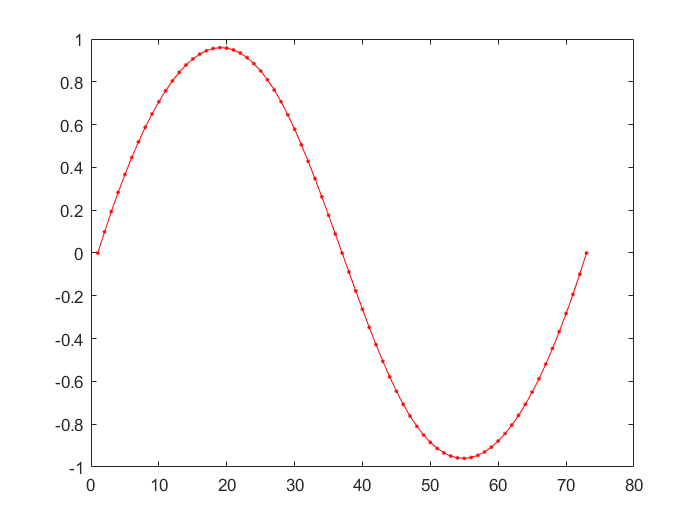

plot(y_spl, 'r.-');

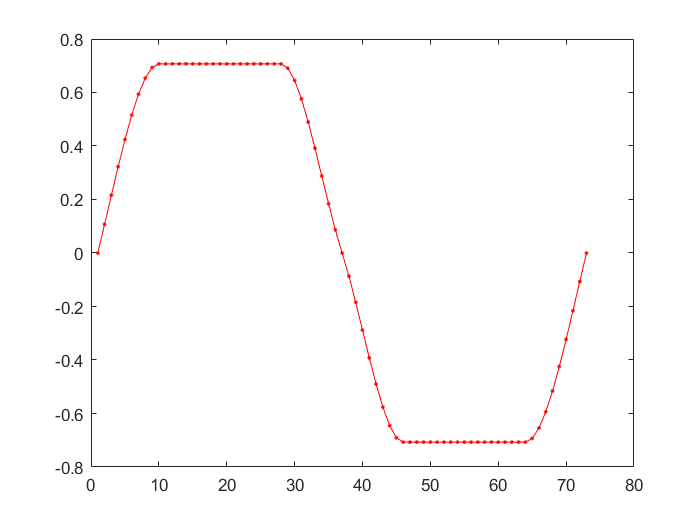

plot(y_pchip,'r.-');

**The best option in this case is SPLINE. This might vary, depending on the type of input provided to the interpolating technique.**

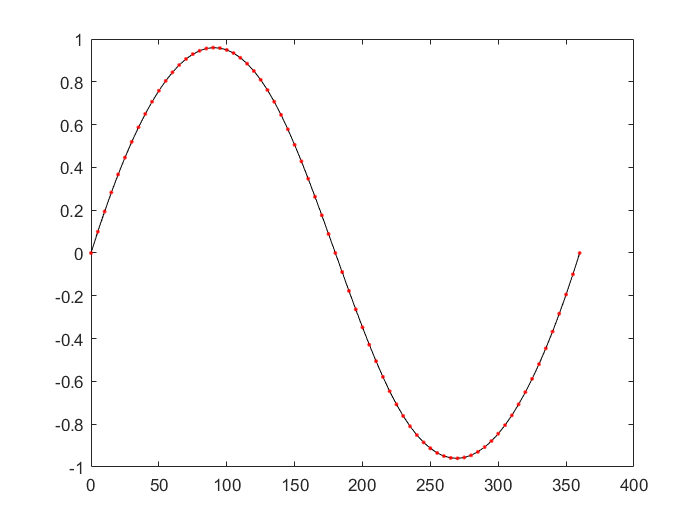

% BEST INTERPOLATION
plot(xq,y_spl,'k-',xq, y_spl, 'r.')

**Q.  Plot the Temperature.xlsx and interpolate data for missing hours.**

filename = 'Temperature.xlsx';
sheet = 1;
xlRange = 'A:B';
subsetA = xlsread(filename,sheet,xlRange)

Error using xlsread (line 139)
XLSREAD unable to open file 'Temperature.xlsx'.
File 'D:\Notes\4th Semester\MATLAB\Statistics\Temperature.xlsx' not found.

**Q. A car takes to move from point A to point B with speed as provided in Car.xlsx. Using correct interpolation techniques compute the speed of the car for 5s, 15s, 25s, 35s ...**

filename = 'Car.xlsx';
sheet = 1;
xlRange = 'A:B';
subsetA = xlsread(filename,sheet,xlRange)'

subsetA =      0    10    20    30    40    50    60    70    80    90
    45    32     0     0     7    12    20    15    29    55


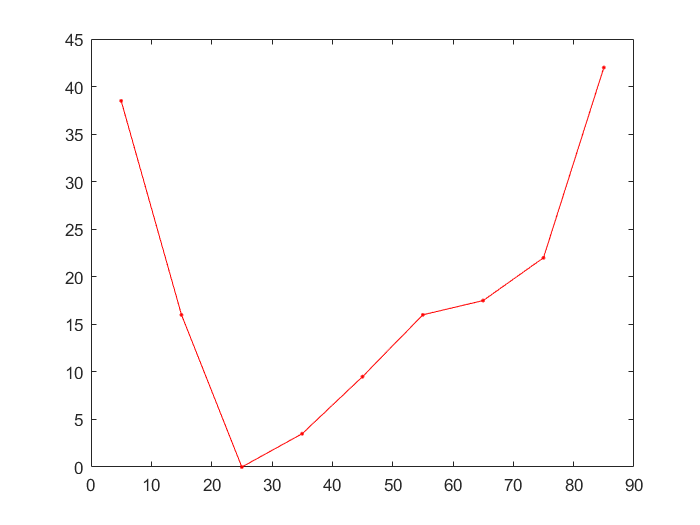

xq = 5:10:95;
y_linear = interp1(subsetA(1,:),subsetA(2,:),xq,'linear');
y_spline = interp1(subsetA(1,:),subsetA(2,:),xq,'spline');
y_pchip = interp1(subsetA(1,:),subsetA(2,:),xq,'pchip');
plot(xq,y_linear, 'r.-');

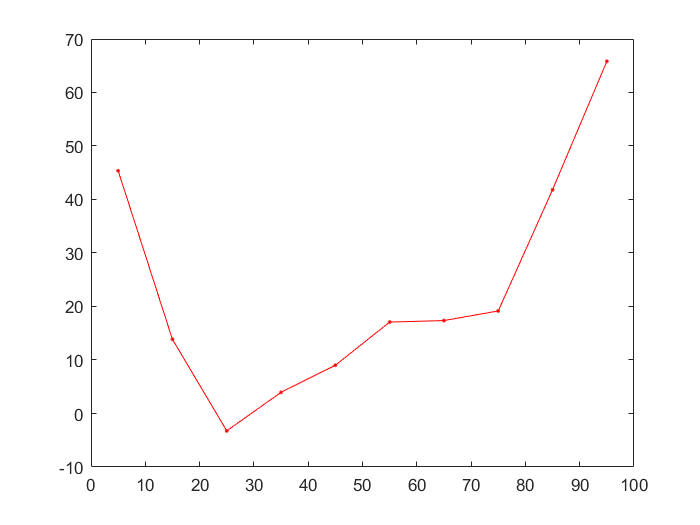

plot(xq,y_spline, 'r.-');

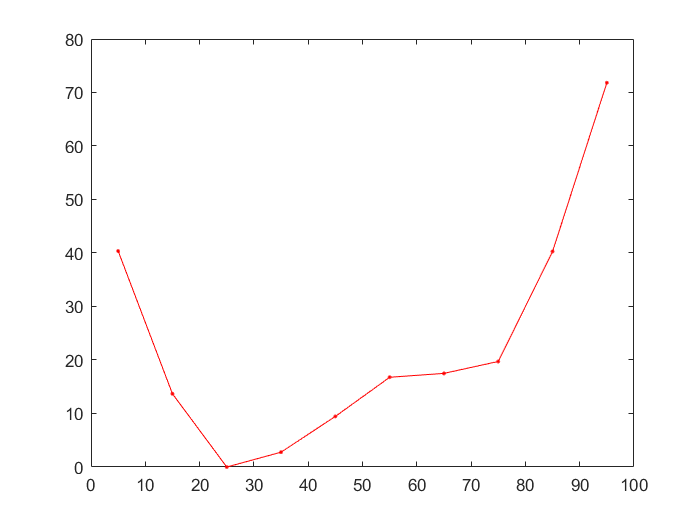

plot(xq,y_pchip,'r.-');

# Extrapolation Techniques

Obtaining the values y for some x which lies outside the provided range of data